# 确认LOG频率

故障未知仿真log的unknown_logger频率是50Hz

这里替换log中的时间采用相对时间

clc
logSampleRate = 50;
 
ulogOBJ = ulogreader("log_1_2021-6-30-08-04-00.ulg");
msg = readTopicMsgs(ulogOBJ);

# 确定unknown_logger的序号

更换log文件后需要修改下面的数值，找到msg中对应的unknown_logger的序号是多少。

% 获取unknown_logger数据
unknown_logger = msg.TopicMessages{32};

% 生成相对时间
log_time = unknown_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate))
% 获取具体数据
h1 = unknown_logger.h1;
h2 = unknown_logger.h2;
h1d= unknown_logger.h1d;
h2d= unknown_logger.h2d;

% 出图
% figure(1)
% plot(relativeTime, h1, relativeTime, h1d);
% figure(2)
% plot(relativeTime, h2, relativeTime, h2d);

画出主轴的跟踪图

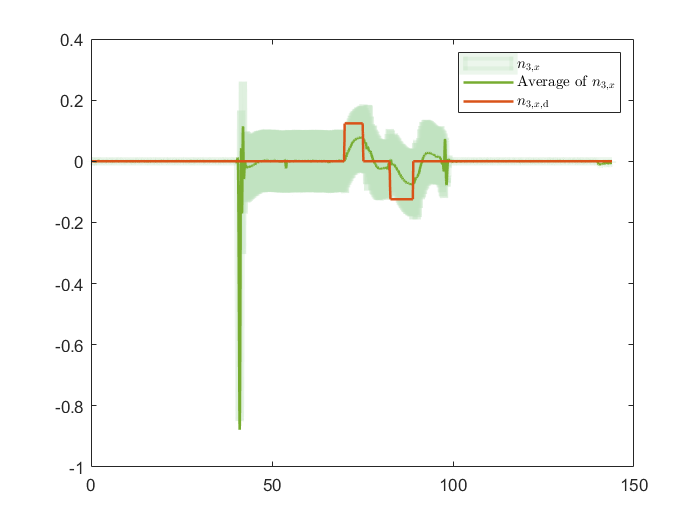

% 进行滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',50);
h1f = filtfilt(d,double(h1));
% 滤波出图
figure(3)
clf
area(relativeTime,h1,'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5)
hold on
plot(relativeTime,h1f,'Color','#77AC30','LineWidth',1.5)
plot(relativeTime,h1d,'Color','#D95319','LineWidth',1.5)
legend('$n_{3,x}$','Average of $n_{3,x}$','$n_{3,x,\mathrm{d}}$',"Interpreter","latex")

% legend('Box',"off")